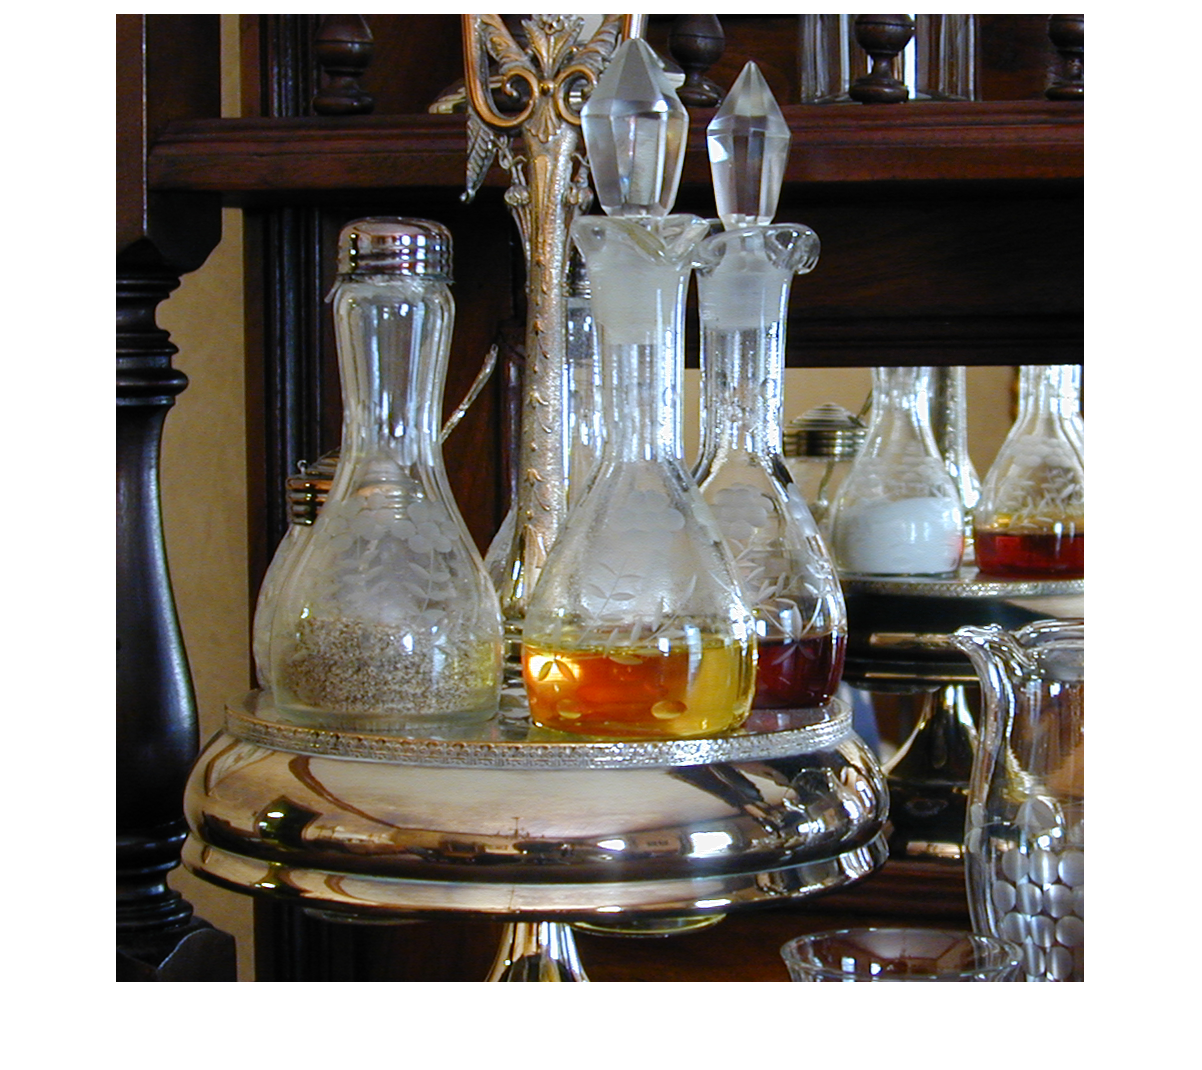

clf; clear;
img = imread("../images/caster_stand.tif");
imshow(img, [])

[M, N, C] = size(img);
gray_img = rgb2gray(img);

prob = zeros([1, 256]);
for i=0:255
    prob(i + 1) = sum(gray_img == i, "all");
end
prob = prob / (M * N);
m_g = sum((0: 255) .* prob, "all");

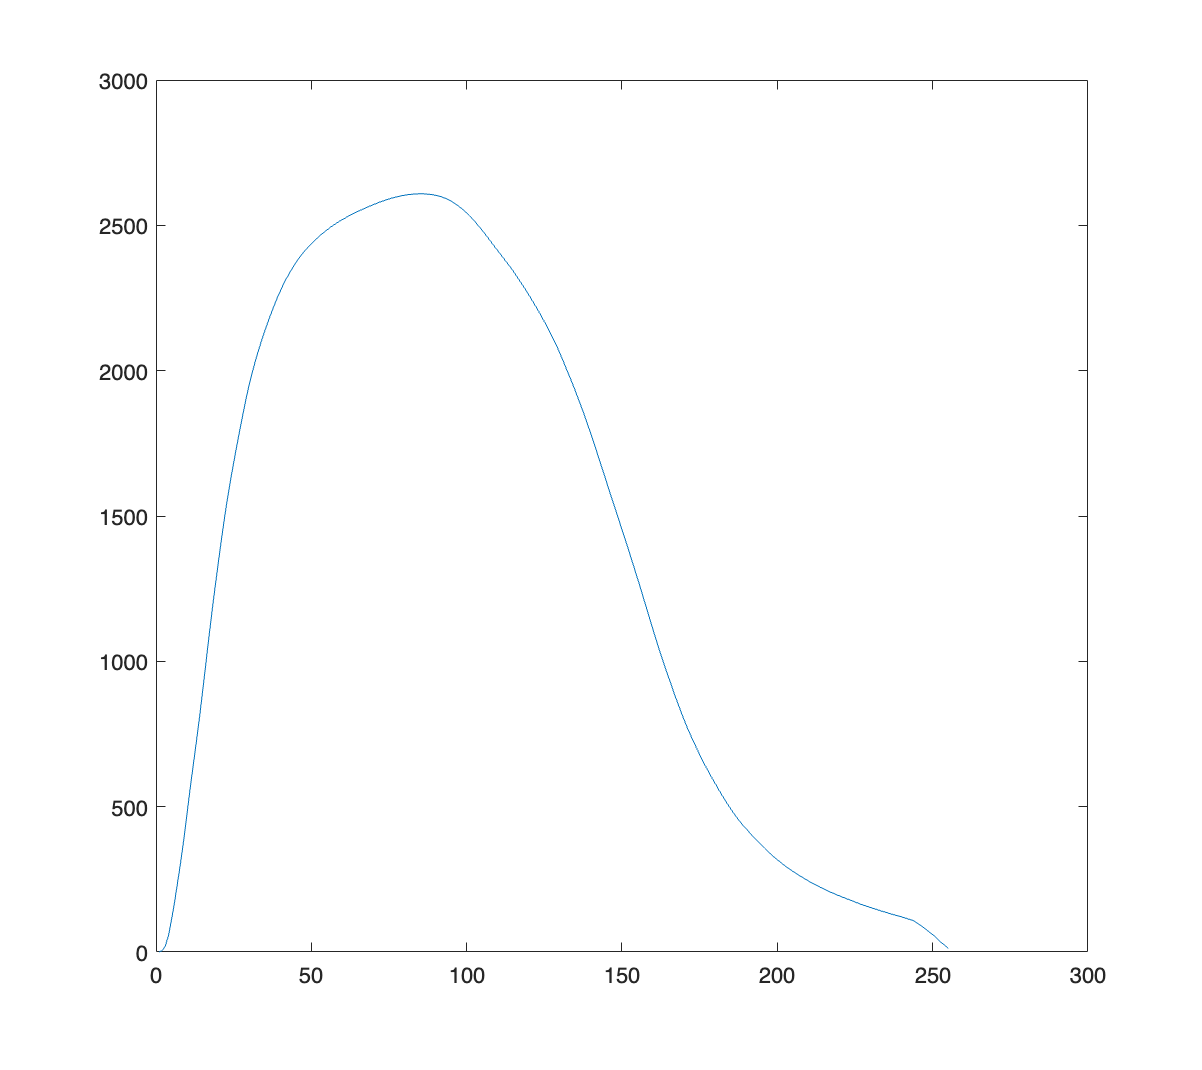

best_T = 0;
best_sigma = -1;
sigma = zeros([1, 255]);
for T=0:254
    P_1 = sum(prob(1: T + 1), "all");
    P_2 = 1 - P_1;
    m_1 = sum((0: T) .* prob(1: (T + 1)), "all");
    m_2 = sum(((T+1): 255) .* prob((T + 2): end), "all");
    sigma_b = P_1 * (m_1 - m_g)^2 + P_2 * (m_2 - m_g)^2; 
    if sigma_b > best_sigma
        best_T = T;
        best_sigma = sigma_b;
    end
    sigma(T + 1) = sigma_b;
end
plot(1: 255, sigma);

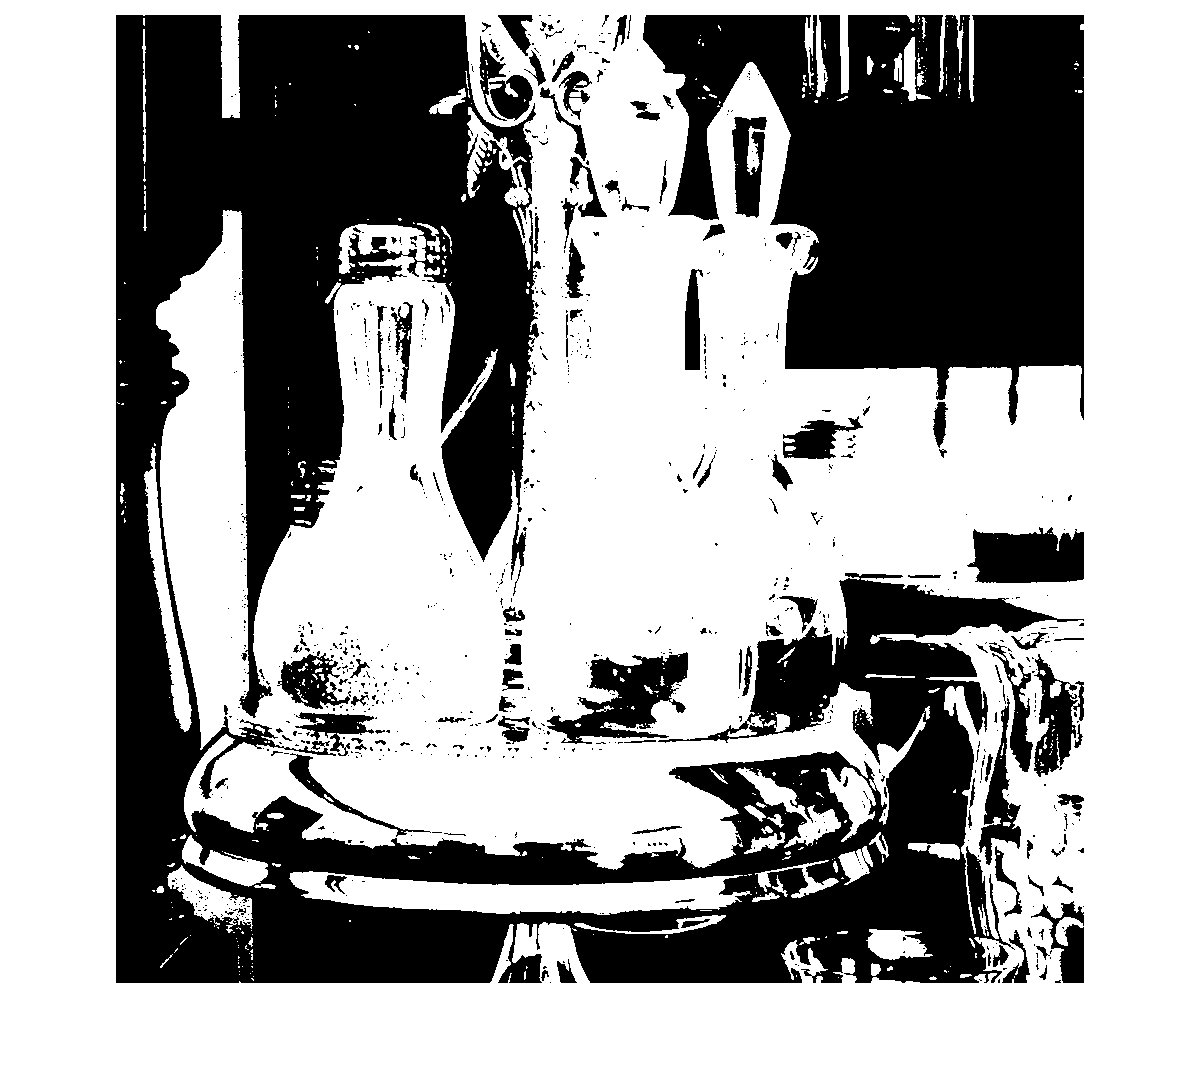

gray_img(gray_img <= best_T) = 0;
gray_img(gray_img > best_T) = 1;
imshow(gray_img, [])